[y,Fs] = audioread("Anote.mp3");
soundsc(y,Fs)


idx1 = 1e4:1.2e4;
signal1 = y(idx1,1)

signal1 =     0.0195
    0.0177
    0.0156
    0.0133
    0.0107
    0.0079
    0.0049
    0.0016
   -0.0018
   -0.0055


tf = (idx1(end)-idx1(1))./Fs

tf = 0.0454

t1 = linspace(0,tf,length(signal1));
Fs

Fs = 44100


Fs2 = 25*600e3

Fs2 = 15000000

carrierFreq = 3e3;
t2 = 0:(1/Fs2):tf

t2 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



t2(end)

ans = 0.0454

t1(end)

ans = 0.0454

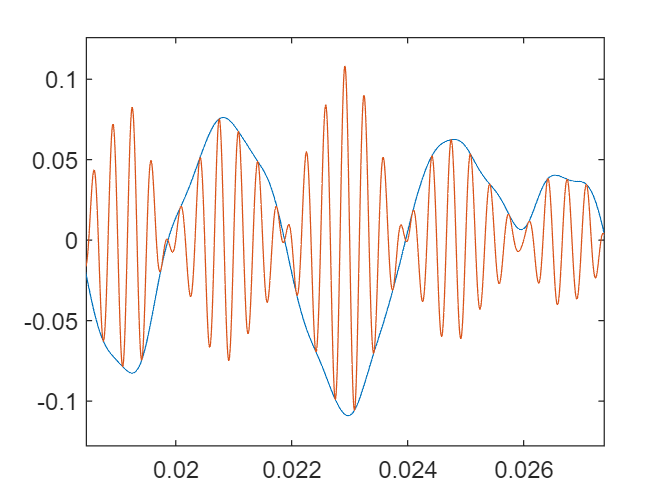

signal2 = interp1(t1,signal1,t2,"spline");


signal3 = signal2.*sin(2*pi*carrierFreq.*t2);


plot(t2,signal2,t2,signal3)